## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Rodrigo Sánchez Molina](https://github.com/rsanchezm98) which is based on the coursery course on deep learning. 

The mnist data on handwritten digits is already preprocessed and ready to use.

Github:[https://github.com/rsanchezm98/neural-network-from-scratch.git](https://github.com/rsanchezm98/neural-network-from-scratch.git)

### NN-Architecture

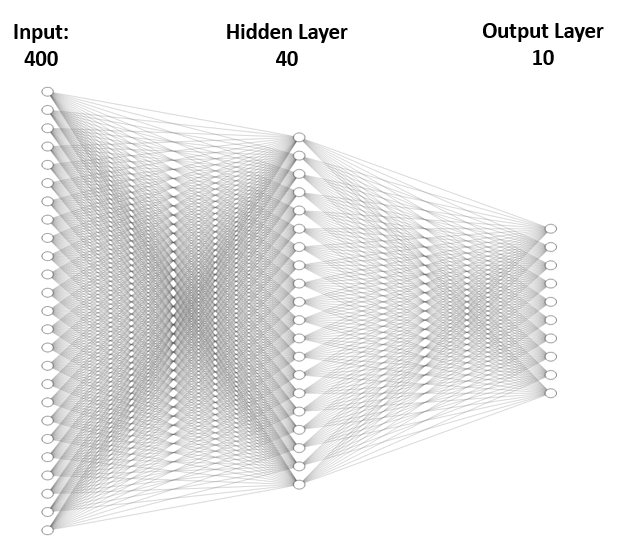

#### Input digits (20X20)

#### Project goal:

The goal of the project is to evaluate different optimization methods to find the optimal weights in the neural network. The methods used are:

- Gradient descent

- Mini-batch gradient descent

- Stochastic gradient descent

- Adagrad.

- Adadelta.

- RMSprop.

- Adam.

#### Data visualization

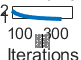

cd 'C:\Users\kevin yar\Desktop\neural_network_mnist\neural_network_mninst'
load('data.mat');


% The dataset size is:
%   X [5000,400] -- 5000 examples and 400 fields
%   y [5000,1]   -- 5000 examples and 1 output

m = size(X, 1); % number of examples

% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel); % this function is property of machineLearningCourse on Coursera

**y is the array that defines which cols in X are which digit**

%% DEFINING THE NEURAL NETWORK ARCHITECTURE

input_layer_size  = 400;  % 20x20 Input Images of Digits
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

layer_sizes = [input_layer_size, 40 ,num_labels];

% we need to create the y_new that is a matrix with size of m*num_labels
y_new = (1:10) == y;

% initialize the weights randomly [the weights have the bias inside on the first column]
for i = 1:(size(layer_sizes, 2)-1)
    initial_weights{i} = randInitializeWeights(layer_sizes(i), layer_sizes(i+1));
end

#### Define the training

#### Ploting the NN efficiency

%% Weight regularization parameter and learning rate
lambda = 1;
alfa = 1;

maxIter = 1000;

loss = [];
count = [];
precisionT = [];
weights = initial_weights;
figure;
ax1 = subplot(2,1,1);
ax2 = subplot(2,1,2);

tic; 
for i = 1:maxIter
    [J, weights] = train(weights, layer_sizes,...
                                   X, y_new, lambda, alfa);
    if mod(i,25) == 0
        loss = [loss;J];
        count = [count;i];
        plot(ax1,count, loss, 'LineWidth', 2);
        title(ax1,'COST EVOLUTION');
        xlabel(ax1,'Iterations');
        ylabel(ax1,'Cost function')
        pred = predict(weights, X, layer_sizes);
        precision = mean(double(pred == y)) * 100;
        precisionT = [precisionT;precision];
        plot(ax2,count, precisionT, 'LineWidth', 2);
        title(ax2,'PRECISION EVOLUTION');
        xlabel(ax2,'Iterations');
        ylabel(ax2,'Precision');
        disp(['Iteration #: ' num2str(i) ' / ' num2str(maxIter) ' | Cost J: ' num2str(J) ' | Precission: ' ...
                num2str(precision)]);
        drawnow();
    end
    
end

Iteration #: 25 / 1000 | Cost J: 2.6735 | Precission: 67.92
Iteration #: 50 / 1000 | Cost J: 1.824 | Precission: 78.5
Iteration #: 75 / 1000 | Cost J: 1.4075 | Precission: 84.14
Iteration #: 100 / 1000 | Cost J: 1.1611 | Precission: 87.06
Iteration #: 125 / 1000 | Cost J: 1.0086 | Precission: 88.92
Iteration #: 150 / 1000 | Cost J: 0.90698 | Precission: 89.48
Iteration #: 175 / 1000 | Cost J: 0.83559 | Precission: 90.16
Iteration #: 200 / 1000 | Cost J: 0.78305 | Precission: 90.64
Iteration #: 225 / 1000 | Cost J: 0.74268 | Precission: 91
Iteration #: 250 / 1000 | Cost J: 0.71046 | Precission: 91.34
Iteration #: 275 / 1000 | Cost J: 0.68396 | Precission: 91.66
Iteration #: 300 / 1000 | Cost J: 0.66161 | Precission: 92.06
Iteration #: 325 / 1000 | Cost J: 0.64237 | Precission: 92.42
Iteration #: 350 / 1000 | Cost J: 0.62554 | Precission: 92.5



finT = toc;


disp(['Time spent on training the net: ' num2str(finT) ' seconds' ])



fprintf("This is code and abowe is text YOu can switch with alt+enter")

### Function section

#### The order of the functions are their order of usage

function [J, newWeights] = train(weights, layer_sizes,...
                                   X, y_new, lambda, alfa)

    
    % Setup some useful variables
    m = size(X, 1);
    %a1 is a matrix with first col (5000 rows) are ones and the rest 400
    %cols with 5000 rows are the data input with each col beeing a digit
    %input
    a1 = [ones(m, 1) X];   

    % You need to return the following variables correctly (?)
    J = 0;
    
    % initialize the sum and the activation matrizes for each layer
    % we have 3 layers input (400), hidden (40) and output (10)
    for i = 1:(size(layer_sizes,2))
        %initialize the matrizes for each layer with zeros for later
        z{i} = zeros(m,layer_sizes(i)+1);
        a{i} = zeros(m,layer_sizes(i)+1);
    end

    %for the input layer 
    a{1} = a1;  

    %% FORDWARD PROPAGATION
    for i = 2:size(layer_sizes,2)
        z{i} = a{i-1}*weights{i-1}';
        a{i} = sigmoid(z{i});
        if i ~= size(layer_sizes,2)
            a{i} = [ones(length(z{i}),1) a{i}];
        end
    end

    % he uses the Binary Cross Entropy Cost Function 
    % cost function for classification
    J = sum(sum(-y_new .* log(a{end}) - (1 - y_new) .* log(1 - a{end}))) / m ;

    % add regularization to the cost function
    regularization = 0;
    for i = 1:(size(layer_sizes,2)-1)
        regularization = regularization + sum(weights{i}(:,2:end).^2,'all');
    end

    regularization =  lambda/(2*m) * regularization;
    J = J + regularization;
    

    %% BACK PROPAGATION 

    % sigmas
    for i = size(layer_sizes,2):-1:2
        if i == size(layer_sizes,2)
            s{i} = a{i} - y_new;
        else
            s{i} = (s{i+1}*weights{i}(:, 2:end)) .* sigmoidGradient(z{i});
        end
        
    end
    % deltas
    for i = 1:(size(layer_sizes,2)-1)
        deltas{i} = s{i+1}'*a{i};
    end


    %% GRADIENT DESCENT
    % with 3 layers we have i from 1 to 2
    for i = 1:(size(layer_sizes,2)-1) 
                     % concat 40x1 zeros to 40x400 weight values 
        p = lambda * [zeros(size(weights{i}, 1), 1), weights{i}(:, 2:end)] / m;

        weight_grad{i} = deltas{i}./m + p;

        newWeights{i} = zeros(size(weights{i}));
        
        newWeights{i}(:,1) = weights{i}(:,1) - alfa*mean(weight_grad{i}(:,1),1);
        newWeights{i}(:,2:end) = weights{i}(:,2:end) - alfa*weight_grad{i}(:,2:end);
        
    end


end

function W = randInitializeWeights(L_in, L_out)

    %W = zeros(L_out, 1 + L_in);
    
    
    epsilon_init = 0.12;
    W = rand(L_out, 1 + L_in) * 2 * epsilon_init - epsilon_init;


end

function [h, display_array] = displayData(X, example_width)
    %DISPLAYDATA Display 2D data in a nice grid
    %   [h, display_array] = DISPLAYDATA(X, example_width) displays 2D data
    %   stored in X in a nice grid. It returns the figure handle h and the 
    %   displayed array if requested.
    
    % Set example_width automatically if not passed in
    if ~exist('example_width', 'var') || isempty(example_width) 
	    example_width = round(sqrt(size(X, 2)));
    end
    
    % Gray Image
    colormap(gray);
    
    % Compute rows, cols
    [m n] = size(X);
    example_height = (n / example_width);
    
    % Compute number of items to display
    display_rows = floor(sqrt(m));
    display_cols = ceil(m / display_rows);
    
    % Between images padding
    pad = 1;
    
    % Setup blank display
    display_array = - ones(pad + display_rows * (example_height + pad), ...
                           pad + display_cols * (example_width + pad));
    
    % Copy each example into a patch on the display array
    curr_ex = 1;
    for j = 1:display_rows
	    for i = 1:display_cols
		    if curr_ex > m, 
			    break; 
		    end
		    % Copy the patch
		    
		    % Get the max value of the patch
		    max_val = max(abs(X(curr_ex, :)));
		    display_array(pad + (j - 1) * (example_height + pad) + (1:example_height), ...
		                  pad + (i - 1) * (example_width + pad) + (1:example_width)) = ...
						    reshape(X(curr_ex, :), example_height, example_width) / max_val;
		    curr_ex = curr_ex + 1;
	    end
	    if curr_ex > m, 
		    break; 
	    end
    end
    
    % Display Image
    h = imagesc(display_array, [-1 1]);
    
    % Do not show axis
    axis image off
    
    drawnow;

end
